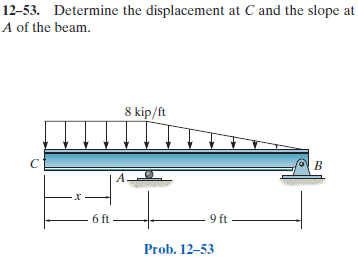

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-53P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-53P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

x = sym('x');
w1(x) = -8*u.kip/u.ft;
w2 = findpoly(1, 'thru', [6*u.ft -8*u.kip/u.ft], [15*u.ft 0]);

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 6*u.ft);
b = b.add('reaction', 'force', 'Rb', 15*u.ft);
b = b.add('distributed', 'force', w1, [0 6]*u.ft);
b = b.add('distributed', 'force', w2, [6 15]*u.ft, [false true]);
b.L = 15*u.ft;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{\left(x-6\,\mathrm{ft}\right)\,\left(5\,x^{3}+30\,x^{2}\,\mathrm{ft}+180\,x\,{\mathrm{ft}}^{2}-7776\,{\mathrm{ft}}^{3}\right)}{15\,\text{E}\,\text{I}}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 6\,\mathrm{ft}\\ \frac{\left(x-6\,\mathrm{ft}\right)\,\left(x-15\,\mathrm{ft}\right)\,\left(x-24\,\mathrm{ft}\right)\,\left(x^{2}-30\,x\,\mathrm{ft}+396\,{\mathrm{ft}}^{2}\right)}{135\,\text{E}\,\text{I}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }6\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{4\,\left(2214\,{\mathrm{ft}}^{3}-5\,x^{3}\right)}{15\,\text{E}\,\text{I}}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 6\,\mathrm{ft}\\ \frac{5\,x^{4}-300\,x^{3}\,\mathrm{ft}+7020\,x^{2}\,{\mathrm{ft}}^{2}-75600\,x\,{\mathrm{ft}}^{3}+300024\,{\mathrm{ft}}^{4}}{135\,\text{E}\,\text{I}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }6\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -4\,x^{2}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 6\,\mathrm{ft}\\ \frac{4\,\left(x-15\,\mathrm{ft}\right)\,\left(x^{2}-30\,x\,\mathrm{ft}+252\,{\mathrm{ft}}^{2}\right)}{27}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }6\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -8\,x\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 6\,\mathrm{ft}\\ \frac{4\,\left(x^{2}-30\,x\,\mathrm{ft}+234\,{\mathrm{ft}}^{2}\right)}{9}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }6\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -8\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 6\,\mathrm{ft}\\ \frac{8\,\left(x-15\,\mathrm{ft}\right)}{9}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }6\,\mathrm{ft}<x \end{array}\right.$$

# reactions and hinges

ra 

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & 88\,\mathrm{kip}\\ \mathrm{Rb} & -4\,\mathrm{kip} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

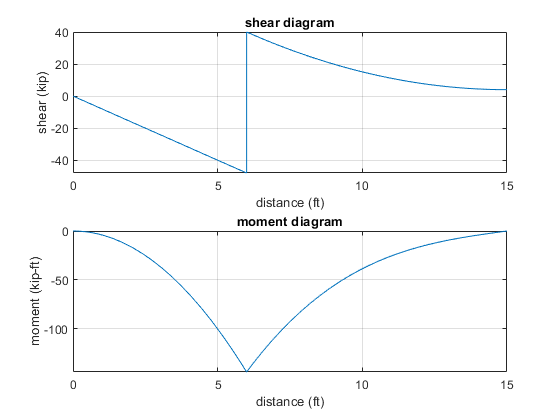

beam.shear_moment(m, v, [0 b.L], {'kip', 'ft'});

# displacements and slopes

y_C = y(0);
y_C_vpa = vpa(y_C) %#ok<NASGU> 

$$y\_C\_vpa = -\frac{3110.4}{\text{E}\,\text{I}}\,{\mathrm{ft}}^{3}\,\mathrm{kip}$$

dy_A = dy(6*u.ft);
dy_A_vpa = vpa(dy_A) %#ok<NASGU> 

$$dy\_A\_vpa = \frac{302.4}{\text{E}\,\text{I}}\,{\mathrm{ft}}^{2}\,\mathrm{kip}$$

# clean up

addvar(y);
setassum(old_assum, 'clear');
clear y_C_vpa dy_A_vpa;
clear old_assum;